tic
clc; clear all; close all;

% Exported Data Format: [ Vessel#  Frame#  MinFrameDistance MaxFrameDistance  ObjectDensity  ]


## Import Data

% Input tau data folder name (INCLUDE FOLDER PATH AND NAME):
object_sourcefolder = 'C:\Users\exx\Desktop\Zach - Active Analysis\2470\neuron_distance_data';

% Input distance transform data folder name for volume calculation (INCLUDE FOLDER PATH AND NAME):
volume_sourcefolder = 'C:\Users\exx\Desktop\Zach - Active Analysis\2470\Intensity_distance_data';

% Input Cortical Layer file name (INCLUDE FOLDER PATH AND NAME):
cortical_sourcefolder = 'C:\Users\exx\Desktop\Zach - Active Analysis\2470\vessel_cortical_data3';

% Max Distance From Vessel (in microns) (Recommended Value 100):

ves_dist = [ 100 ];

% Minium Distance From Vessel (in microns) (Recommended Value -10):

min_dist = [ -10 ];

% Resolution in microns? (Recommended Value: 1):

res = [ 1 ];

% Frame width (# Microns) (Recommended Value: 10):

frame_w = [ 100 ];

% Voxel Size (Obtain from Imaris: Edit -> Image Properties):
%              [   X     Y      Z   ]
voxel =        [ 0.731 0.731    3.95   ];

% Data Output:

% Folder (Include Name + Path):
outputfoldername = 'C:\Users\exx\Desktop\Zach - Active Analysis\2470\Neuron_density_data_100';

% File (DO NOT include file type, ie. .csv):
outputname = 'Human2470_neuron_density_data'; 


## Load Data

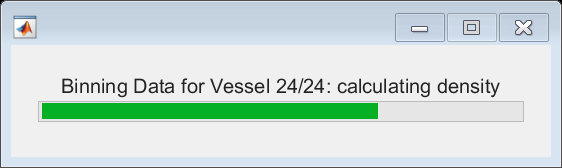



% # Bins along vessel
nbins_length = 5;

fcontent = dir(fullfile(object_sourcefolder, '*.txt')); %fcontent is a column vector of structures

l1 = 1;

object_data = [];

Distance_data = [];

n = length(fcontent');

endrow = 0;
final_data = [];

f = waitbar(0,sprintf('Reading data for Vessel 1/%d: tau data',n));

for b = 1:n

filename = fcontent(b).name;

fcontent2 = dir(fullfile(cortical_sourcefolder, '*.txt')); %fcontent is a column vector of structures
filename2 = fcontent2(b).name;

[pathstr,name,ext] = fileparts(filename);

name_parts = regexp(name,'_','split');

vesnum1 = name_parts{3};

[pathstr2,name2,ext2] = fileparts(filename2);

name_parts2 = regexp(name2,'_','split');

vesnum2 = name_parts2{3};

if vesnum1 ~= vesnum2
    error(sprintf('VESSEL MATCH ERROR: Cortical layer and object data do not match (cortical: Vessel %s intensity: Vessel %s )',vesnum2,vesnum1));
    break
end

waitbar(0,f,sprintf('Reading data for Vessel %d/%d: tau data',b,n));

    sizes = [];
        n1 = b;
        n2 = b;
        object_data = [];
        bin_edges = [];
        surface_data = [];
        bin_numbers = [];
        clc
        % close all

fcontent = dir(fullfile(object_sourcefolder, '*.txt')); %fcontent is a column vector of structures

% Load Object data 

object_data = readmatrix(fullfile(object_sourcefolder,filename));

% Load vessel cortical data

cortical_data = readmatrix(fullfile(cortical_sourcefolder,filename2));


% % Remove data where Tau is within blood vessel and greater than ves_dist
% % away
% 
% object_data_backup = object_data;
% edges = [min_dist ves_dist];
% 
% idx = discretize(object_data(:,6),edges)
% 
% idx2 = find(isnan(idx))
% object_data(idx2,:) = [];


if isempty(object_data)
    object_data = zeros(1,6)-min_dist-100;
end

waitbar(0.1,f,sprintf('Reading data for Vessel %d/%d: volume data',b,n));

% Read volume data

fcontent = dir(fullfile(volume_sourcefolder, '*.txt')); %fcontent is a column vector of structures

   filename = fcontent(b).name;
   Distance_data_single = [];
   Distance_data_single = readmatrix(fullfile(volume_sourcefolder,filename));
   Distance_data = [Distance_data_single(:,1:3) zeros(length(Distance_data_single(:,1)),1) Distance_data_single(:,5) Distance_data_single(:,6)];


% % if isempty(object_data)
% %     continue
% % end

% Remove data where Tau is within blood vessel and greater than ves_dist
% away
Distance_data_backup = Distance_data;

object_data_backup = object_data;

object_data(:,6) = object_data(:,4);

%% Bin Data by Surface Frames

% vesnum = vessel ID    g = frame ID

fcontent = dir(fullfile(object_sourcefolder, '*.txt')); %fcontent is a column vector of structures
filename = fcontent(b).name;
[pathstr,name,ext] = fileparts(filename);

name_parts = regexp(name,'_','split');
vesnum = str2num(name_parts{3});

fcontent2 = dir(fullfile(volume_sourcefolder, '*.txt')); %fcontent is a column vector of structures
filename2 = fcontent2(b).name;
[pathstr2,name2,ext2] = fileparts(filename2);

name_parts2 = regexp(name2,'_','split');
vesnum2 = str2num(name_parts2{3});
%%

if vesnum ~= vesnum2
    error('VESSEL MATCH ERROR: Object and volume data are from different vesels (obj: Vessel %d Volume: Vessel %d)',vesnum,vesnum2);
end
%%


waitbar(0.6,f,sprintf('Binning Data for Vessel %d/%d: distance away from vessel',b,n));


## Bin by distance away



edges_away = min_dist-0.5:res:ves_dist+0.5;

idx_tau_away = discretize(object_data(:,6),edges_away);

idx_dist_away = discretize(Distance_data(:,6),edges_away);

waitbar(0.65,f,sprintf('Binning Data for Vessel %d/%d: distance along vessel',b,n));


## Bin by distance along



maxlength = (ceil(max(Distance_data(:,5)/frame_w))*frame_w);

edges_along = 0:frame_w:maxlength;

idx_tau_along = discretize(object_data(:,5),edges_along);

idx_dist_along = discretize(Distance_data(:,5),edges_along);

idx_cortical_along = discretize(cortical_data(:,6),edges_along);


## Store bin coordinates & calculate density

waitbar(0.7,f,sprintf('Binning Data for Vessel %d/%d: calculating density',b,n));

object_data(:,7:8) = [idx_tau_along idx_tau_away];

Distance_data(:,7:8) = [idx_dist_along idx_dist_away];

cortical_data(:,7) = [idx_cortical_along];

object_data(any(isnan(object_data), 2), :) = [];
Distance_data(any(isnan(Distance_data), 2), :) = [];
cortical_data(any(isnan(cortical_data), 2), :) = [];

final_data(endrow+1:endrow+length(edges_along)-1,:) = zeros(length(edges_along)-1,length(edges_away)+4);

parfor i = 1:maxlength/frame_w

    idx = find(cortical_data(:,7) == i);
    if isempty(idx)
        cortical_layer = 0;
    else
    cortical_layer = round(mean(cortical_data(idx,5)));
    end
    frame_low = i*frame_w-frame_w;
    frame_high = i*frame_w;
    prelim_frame_data = [vesnum i cortical_layer frame_low  frame_high];
    prelim_data(i,:) = prelim_frame_data;

end

final_data(endrow+1:endrow+length(prelim_data(:,1)),1:5) = prelim_data;

if isempty(object_data)
endrow = length(final_data(:,1));
object_data = [];
Distance_data = [];
continue
end

clear i;

parfor i = 1:length(object_data(:,1))

    dist_data_temp = Distance_data(:,7:8);
    object_data_temp = object_data(:,7:8);

    edges1 = [object_data_temp(i,1)-0.5;object_data_temp(i,1)+0.5];

    idx_tau = discretize(object_data_temp(:,1),edges1);
    idx_dist = discretize(dist_data_temp(:,1),edges1);

    object_data_temp(:,1) = idx_tau;
    dist_data_temp(:,1) = idx_dist;

    edges2 = [object_data_temp(i,2)-0.5;object_data_temp(i,2)+0.5];

    idx_tau2 = discretize(object_data_temp(:,2),edges2);
    idx_dist2 = discretize(dist_data_temp(:,2),edges2);

    object_data_temp(:,2) = idx_tau2;
    dist_data_temp(:,2) = idx_dist2;

    object_data_temp(any(isnan(object_data_temp), 2), :) = [];
    dist_data_temp(any(isnan(dist_data_temp), 2), :) = [];

    volume = length(dist_data_temp(:,1))*(voxel(1)*voxel(2)*voxel(3));

    density = length(object_data_temp(:,1))/volume;

    rowidx = object_data(i,7);
    colidx = object_data(i,8);

    prelim_den_data(i,:) = [density rowidx colidx];

    object_data_temp = [];
    dist_data_temp = [];
    idx_tau = [];
    idx_dist = [];
    idx_tau2 = [];
    idx_dist2 = [];

end

for i = 1:length(prelim_den_data(:,1))

density = prelim_den_data(i,1);
rowidx = prelim_den_data(i,2);
colidx = prelim_den_data(i,3);
final_data(endrow+rowidx,colidx+5) = density;

end

endrow = length(final_data(:,1));
object_data = [];
Distance_data = [];
prelim_data = [];
prelim_den_data = [];

end


%% Headers
sampleID = name_parts{1};

samplenumber = sampleID;
samplenumber = str2num(samplenumber(isstrprop(samplenumber, 'digit')));

samplecolumn = ones(size(final_data,1),1).*samplenumber;

final_data = [samplecolumn final_data];

intensity_headers = [min_dist:ves_dist];
intensity_headerstemp = {};
for i = 1:length(intensity_headers)
    intensity_headerstemp(:,i) = {append(sprintf('%g',intensity_headers(1,i)),' um Density (#/um^3)')};
end
intensity_headers = intensity_headerstemp;
headers = cell2table({ 'SampleID' 'Vessel#'  'Frame#'  'MinFrameDistance' 'MaxFrameDistance' intensity_headers{:}});


## Save Data (header exported in separate file)

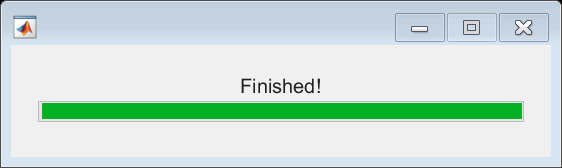


writetable(headers,append(outputfoldername,'\',outputname,'_HEADERS.csv'));
writematrix(final_data,append(outputfoldername,'\',outputname,'.csv'));
waitbar(1,f,'Finished!');

toc

Elapsed time is 1242.645478 seconds.
